x = imread('coins.png')

x = 246×300 uint8 matrix
   49   50   48   49   48   48   49   50   50   50   50   49   49   48   50   50   51   50   49   49   48   50   52   50   50   49   50   51   50   49   50   49   49   51   51   50   51   51   52   51   51   51   51   50   52   52   51   52   52   53
   47   47   49   48   50   49   50   48   49   49   49   49   48   48   49   48   49   50   50   50   49   49   49   49   50   49   49   50   50   51   51   52   50   52   50   50   50   51   52   50   51   52   52   52   51   50   50   50   50   50
   48   48   49   49   49   49   49   49   49   50   49   50   50   50   49   49   49   49   50   49   48   48   50   50   50   51   50   50   51   51   51   50   49   50   50   50   50   49   51   51   50   51   52   53   52   52   53   51   51   52
   48   50   49   48   48   50   49   50   50   48   50   49   50   50   49   50   49   50   49   50   50   48   50   52   50   49   50   51   50   50   51   49   49   49   50   50   50   49   51   51   50   52   52   53  

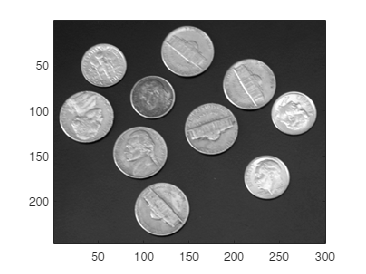

imagesc(x); colormap(gray); axis image

minimal = min(x(:))

minimal = uint8
23

hx=[1,0,-1;
2,0,-2;
1,0,-1]

hx =      1     0    -1
     2     0    -2
     1     0    -1



gx = conv2(x,hx, 'same')

gx =    147     0    -1     1    -1     2     3     1     1     0    -2    -3    -3     3     4     2     2    -3    -2    -3     1     8     0    -3    -2    -1     5     1    -3     1     1    -3     4     4    -4     0     3     4    -1    -3     2     1    -2     1     2    -3     0     2     2     3
   192     4     2     2     1     1     0    -1     3     0    -1    -2    -3     2     1     1     4     1    -1    -5    -2     6     2     0     0    -2     3     3     1     2     1    -5     2     3    -5     0     2     6     0    -4     4     4     1    -1    -3    -2    -1    -1     2     3
   193     5     1     0     3     1    -1     0     1     0     1     1     0    -2    -2     0     2     3     0    -4    -5     4     8     1    -1    -1     1     3     2     2    -2    -7     0     3    -1     0    -2     5     5    -4     3     7     5    -2    -4     3    -3    -5     1     1
   196     2    -3     1     5     1     1     2    -5     0     3     1     2    -4    -1  

gx(1,1)

ans = 147

x(1:4,1:4)

ans = 4×4 uint8 matrix
   49   50   48   49
   47   47   49   48
   48   48   49   49
   48   50   49   48


hy = rot90(hx,-1);

gy = conv2(x,hy,'same')

gy =    141   190   193   195   197   198   197   195   195   196   196   195   193   193   194   194   196   199   200   199   197   196   196   197   198   197   197   199   201   203   205   205   204   204   202   200   201   204   205   203   204   207   208   207   204   201   200   200   200   201
    -4    -4     0     2     3     3     0    -3    -3    -2    -1     2     5     4    -1    -5    -6    -3     1     1    -2    -6    -6    -2     2     4     1    -1     3     6     5     3     0    -3    -3    -2    -4    -6    -4    -2    -2     0     5     7     3     2     3    -1    -4    -5
     5     7     3    -2    -3    -1     1     4     3     0     1     3     6     6     4     4     2    -1    -2     0     1     0     4     7     3     1     3     3     0    -2    -4    -7    -8    -7    -3     0    -2    -5    -3     0    -1    -1     1     2     4     9    11     9     7     5
     0    -2    -5    -3     1     1     1     2    -1    -4    -3    -3    -4    -4    -3  

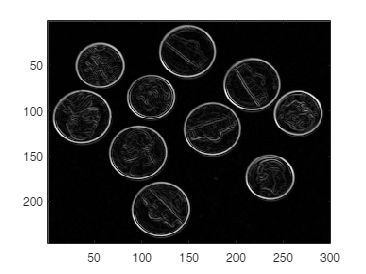

gmag=sqrt(gx.^2 + gy.^2);

imagesc(gmag)

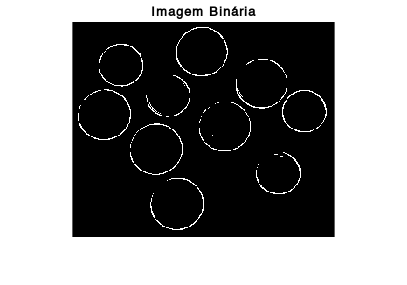

% Definindo o limiar como metade do valor máximo de gmag
limiar = 0.5 * max(gmag(:));

% Criando a imagem binária
imagem_binaria = gmag > limiar;

% Exibindo a imagem binária
figure;
imshow(imagem_binaria);
title('Imagem Binária');